syms u
rainbow_road_center_line = [
            0.3960 * cos(2.65 * (u + 1.4)),
            -0.99 * sin(u + 1.4)
];

neato_max_speed = 0.3;
neato_min_speed = -0.3;
wheel_dist = 0.245;

u_range = [0, 3.2];
full_u_range = linspace(u_range(1), u_range(2), 100);
magnitude = @(vec) sqrt(sum(vec.^2));

rainbow_road_center_line_vel = [diff(rainbow_road_center_line(1)), diff(rainbow_road_center_line(2))];
rainbow_road_center_line_speed = magnitude(rainbow_road_center_line_vel);
rainbow_road_center_line_tangent_vec = rainbow_road_center_line_vel ./ rainbow_road_center_line_speed;
rainbow_road_center_line_tangent_vec_deriv = diff(rainbow_road_center_line_tangent_vec);
rainbow_road_center_line_norm_vec = rainbow_road_center_line_tangent_vec_deriv ./ magnitude(rainbow_road_center_line_tangent_vec_deriv);

rainbow_road_center_line_x(u) = rainbow_road_center_line(1);
rainbow_road_center_line_y(u) = rainbow_road_center_line(2);
rainbow_road_center_line_pos_data_x = double(rainbow_road_center_line_x(full_u_range));
rainbow_road_center_line_pos_data_y = double(rainbow_road_center_line_y(full_u_range));
rainbow_road_center_line_tangent_vec_x(u) = rainbow_road_center_line_tangent_vec(1);
rainbow_road_center_line_tangent_vec_y(u) = rainbow_road_center_line_tangent_vec(2);
rainbow_road_center_line_norm_vec_x(u) = rainbow_road_center_line_norm_vec(1);
rainbow_road_center_line_norm_vec_y(u) = rainbow_road_center_line_norm_vec(2);

tangent_vec_3d = [rainbow_road_center_line_tangent_vec(1), rainbow_road_center_line_tangent_vec(2), 0];
tangent_vec_deriv = diff(tangent_vec_3d);

rainbow_road_axis_of_rotation = cross(tangent_vec_3d, tangent_vec_deriv);
rainbow_road_angular_velocity(u) = magnitude(rainbow_road_axis_of_rotation);

rainbow_road_vel_left = (rainbow_road_center_line_vel - (wheel_dist / 2) * rainbow_road_angular_velocity) .* rainbow_road_center_line_tangent_vec;
rainbow_road_vel_right = (rainbow_road_center_line_vel + (wheel_dist / 2) * rainbow_road_angular_velocity) .* rainbow_road_center_line_tangent_vec;

rainbow_road_vel_left_x(u) = rainbow_road_vel_left(1);
rainbow_road_vel_left_y(u) = rainbow_road_vel_left(2);
rainbow_road_vel_right_x(u) = rainbow_road_vel_right(1);
rainbow_road_vel_right_y(u) = rainbow_road_vel_right(2);
left_vel_x_data = double(subs(rainbow_road_vel_left_x, u, full_u_range));
left_vel_y_data = double(subs(rainbow_road_vel_left_y, u, full_u_range));
right_vel_x_data = double(subs(rainbow_road_vel_right_x, u, full_u_range));
right_vel_y_data = double(subs(rainbow_road_vel_right_y, u, full_u_range));


PLOTS (6.1, 6.2)

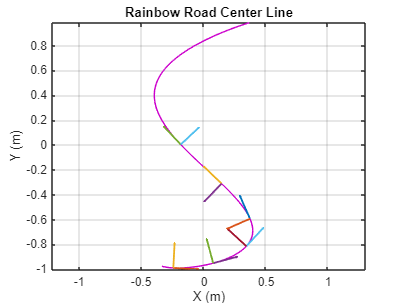

figure;
plot(rainbow_road_center_line_pos_data_x, rainbow_road_center_line_pos_data_y, Color=[0.8, 0, 0.8]); hold on
    for data_val = 5:10:60
        quiver( ...
            rainbow_road_center_line_pos_data_x(data_val), ...
            rainbow_road_center_line_pos_data_y(data_val), ...
            double(rainbow_road_center_line_tangent_vec_x(full_u_range(data_val))), ...
            double(rainbow_road_center_line_tangent_vec_y(full_u_range(data_val))), ...
            0.20, ...
            LineWidth=1.5 ...
        )
        quiver( ...
            rainbow_road_center_line_pos_data_x(data_val), ...
            rainbow_road_center_line_pos_data_y(data_val), ...
            double(rainbow_road_center_line_norm_vec_x(full_u_range(data_val))), ...
            double(rainbow_road_center_line_norm_vec_y(full_u_range(data_val))), ...
            0.20, ...
            LineWidth=1.5 ...
        )
    end
    title("Rainbow Road Center Line")
    xlabel("X (m)"); ylabel("Y (m)")
    grid on
    axis equal;
hold off

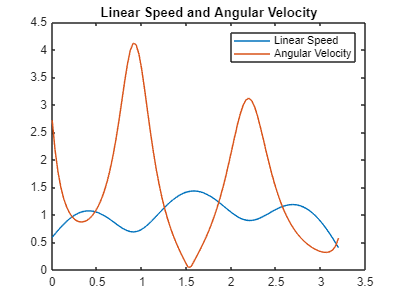


figure;
plot(full_u_range, double(subs(rainbow_road_center_line_speed, u, full_u_range))); hold on
    plot(full_u_range, double(subs(rainbow_road_angular_velocity, u, full_u_range)));
    legend("Linear Speed", "Angular Velocity")
    title("Linear Speed and Angular Velocity")
hold off

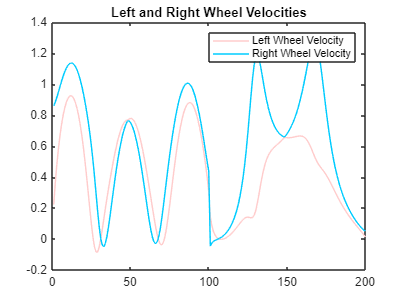


figure;
plot(double(subs(rainbow_road_vel_left, u, full_u_range)), Color=[1, 0.8, 0.8]); hold on
    plot(double(subs(rainbow_road_vel_right, u, full_u_range)), Color=[0, 0.8, 1]);
    title("Left and Right Wheel Velocities")
    legend("Left Wheel Velocity", "Right Wheel Velocity")
hold off